# Speech Emotion Recognition (Monolingual)

clear;              % clear all the workspace
clc;                % clear all the command window
addpath 'D:\Users\Y.H.Tian\Desktop\学习\UOG\Msc Project\code\Tian\SER_Library_Tian'

t1 = clock;         % tick

## Database selection

Database = "RAVDESS";

if Database == "EMODB"
    % add the path of the EMODB database
    audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/EMODB/wav';
    % create a datastore for the EMODB
    audio_ds =  audioDatastore(audio_data_path,'FileExtensions','.wav');
    % select specific emotions in the EMODB (6 common emotions in this case)
    audio_ds = creat_datastore_fit_type(audio_ds,1,'W','E','A','F','N','T',nan,nan,nan,nan);
end
if Database == "RAVDESS"
    audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/RAVDESS_16000';
    audio_ds =  audioDatastore(audio_data_path,'FileExtensions','.wav');
    audio_ds = creat_datastore_fit_type(audio_ds,12,'5','7','6','3','1','4',nan,nan,nan,nan);
end
if Database == "SAVEE"
    audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/SAVEE_16000';
    audio_ds =  audioDatastore(audio_data_path,'FileExtensions','.wav');
    audio_ds = creat_datastore_fit_type(audio_ds,2,'n','h','s','f','d','a',nan,nan,nan,nan);
end
if Database == "RAVDESS_prep"
    

    *If use prepared RAVDESS, please specify settings below.*

    white_noise = false;
    Butter =  false;
    Butter_fc = 2000;         % 0 to 8000Hz (0-fs/2)   
    prepare_RAVDESS(white_noise,Butter,Butter_fc);
    audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/Temp';
    audio_ds =  audioDatastore(audio_data_path,'FileExtensions','.wav');
    audio_ds = creat_datastore_fit_type(audio_ds,12,'5','7','6','3','1','4',nan,nan,nan,nan);
end
reset(audio_ds); 
audio_ds = put_emotion_labels(audio_ds);      % put emotion labels on the datastore

## Feature Extraction

- **Framing process**

  *Please specify settings for framing process below.*

% aFE and other featrue extraction settings, according to the basic experimental settings
fs =            16000;        % sample rate be 16000Hz  
window_length = 0.025;        % Window length 25ms
overlap =       0.75;        % overlap 75%
overlap_length = window_length*overlap;

- **Select features**

% creat aFE
use_gtcc = true;
use_mfcc = false;
use_pitch = false;
use_zcr = false;

 *Please specify settings for features below.*

gtcc_coe = 30;
mfcc_coe = 27;

if (use_pitch == 1)&&(use_gtcc == 1)&&(use_mfcc == 0)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "gtcc",true, ...                                                % extract gtcc feature
    "pitch",true ...
    );
    setExtractorParams(aFE,"gtcc","NumCoeffs",gtcc_coe);
    setExtractorParams(aFE,"erbSpectrum","NumBands",32,"FrequencyRange",[50 8000],"SpectrumType","magnitude"); 
    setExtractorParams(aFE,"pitch","Range",[50 700],"MedianFilterLength",3);
end
if (use_pitch == 0)&&(use_gtcc == 1)&&(use_mfcc == 0)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "gtcc",true ...                                                % extract gtcc feature
    );
    setExtractorParams(aFE,"gtcc","NumCoeffs",gtcc_coe);
    setExtractorParams(aFE,"erbSpectrum","NumBands",32,"FrequencyRange",[50 8000],"SpectrumType","magnitude"); 
end
if (use_pitch == 1)&&(use_gtcc == 0)&&(use_mfcc == 1)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "mfcc",true, ...                                                 % extract mfcc feature
    "pitch",true ...
    );
    setExtractorParams(aFE,"mfcc","NumCoeffs",mfcc_coe);
    setExtractorParams(aFE,"pitch","Range",[50 700],"MedianFilterLength",3);
end
if (use_pitch == 0)&&(use_gtcc == 0)&&(use_mfcc == 1)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "mfcc",true ...                                                 % extract mfcc feature
    );
    setExtractorParams(aFE,"mfcc","NumCoeffs",mfcc_coe);
end
if (use_pitch == 1)&&(use_gtcc == 1)&&(use_mfcc == 1)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "gtcc",true, ...                                                % extract gtcc feature
    "mfcc",true, ...                                                 % extract mfcc feature
    "pitch",true...
    );
    setExtractorParams(aFE,"gtcc","NumCoeffs",gtcc_coe);
    setExtractorParams(aFE,"erbSpectrum","NumBands",32,"FrequencyRange",[50 8000],"SpectrumType","magnitude"); 
    setExtractorParams(aFE,"mfcc","NumCoeffs",mfcc_coe);
    setExtractorParams(aFE,"pitch","Range",[50 700],"MedianFilterLength",3);
end
if (use_pitch == 0)&&(use_gtcc == 1)&&(use_mfcc == 1)
    aFE = audioFeatureExtractor( ...             % ask the MATLAB help to extract features with parameters:
    "SampleRate", fs, ...                                           % fs
    "Window",hamming(round(window_length*fs),"periodic"), ...       % Window length
    "OverlapLength",round(overlap_length*fs), ...                   % overlap 75% (0.025*75%)
    "gtcc",true, ...                                                % extract gtcc feature
    "mfcc",true ...                                                 % extract mfcc feature
    );
    setExtractorParams(aFE,"gtcc","NumCoeffs",gtcc_coe);
    setExtractorParams(aFE,"erbSpectrum","NumBands",32,"FrequencyRange",[50 8000],"SpectrumType","magnitude"); 
    setExtractorParams(aFE,"mfcc","NumCoeffs",mfcc_coe);
end

feature_label = creat_feature_label(aFE, use_zcr);       % creat a label indicates what feature is the column represent in the table (provided below) (calculated automatically by MATLAB)

- **Voice Activity Detection**

VAD_flag = true;

*Please specify settings for Voice Activity Detection below*

% adjust "threshold" argument
pwrThreshold = -60;         % power threshold, -50dB as default
freqThreshold = 1000;        % frequency threshold 1000Hz as default

- **Feature Extraction**

% automatic feature extraction
if VAD_flag == 1
    feature_ds = transform(audio_ds,@(audio_in, info_in) feature_extraction_voicing(pwrThreshold, freqThreshold, audio_in, info_in, aFE, use_zcr), "IncludeInfo",true);           
end
if VAD_flag == 0
    feature_ds = transform(audio_ds,@(audio_in, info_in) feature_extraction(audio_in, info_in, aFE, use_zcr), "IncludeInfo",true);           
end
t2 = clock;         
feature = readall(feature_ds);   
% put feature labels on the result table from the previous step (For easy observation)
feature = cell2table(feature);
feature.Properties.VariableNames = feature_label;
feature.Emotion = categorical(feature.Emotion);
% Normalization
Normalize_features = table2array(feature(:,1:end-1));
m = mean(Normalize_features);
s = std(Normalize_features);
Normalize_features = (Normalize_features-m)./s;
feature(:,1:end-1) = array2table(Normalize_features);
t3 = clock; 
t_feature_extraction=etime(t3,t2);

*Feature extraction time (seconds):*

t_feature_extraction

t_feature_extraction = 122.9970

## Validation and Results

% leave 5% out validation
predictors = feature(:, 1:end-1);
response = feature.Emotion;
cvp = cvpartition(response, 'Holdout', 0.05);

% the training data
predictors_train = predictors(cvp.training, :);
response_train =  response(cvp.training, :);

- **Model selection**

% the model
model_selection = "KNN"

model_selection = "KNN"

if model_selection == "KNN"
    mdl = fitcknn(...
        predictors_train, ...
        response_train, ...
        'Distance', 'Euclidean', ...
        'Exponent', [], ...
        'NumNeighbors', 5, ...
        'DistanceWeight', 'SquaredInverse', ...
        'Standardize', false, ...
        'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));
end
if model_selection == "SVM"
    template = templateSVM(...
        'KernelFunction', 'rbf', ...
        'PolynomialOrder', [], ...
        'KernelScale', 1.8918, ...
        'BoxConstraint', 89.577, ...
        'Standardize', true);
    options = statset('UseParallel',true);
    mdl = fitcecoc(... 
        predictors_train, ...
        response_train, ...
        'Learners',template,...
        'Coding','onevsone',...
        'ClassNames', categorical({'anger'; 'disgust'; 'fear'; 'happiness'; 'neutral'; 'sadness'}));
end
% the test data
predictors_test = predictors(cvp.test, :);
response_test =  response(cvp.test, :);

% validation
[validationPredictions, validationScores] = predict(mdl, predictors_test);

correctPredictions = (validationPredictions == response_test);
isMissing = ismissing(response_test);
correctPredictions = correctPredictions(~isMissing);
validationAccuracy = sum(correctPredictions)/length(correctPredictions);

- **Confusion matrix:**

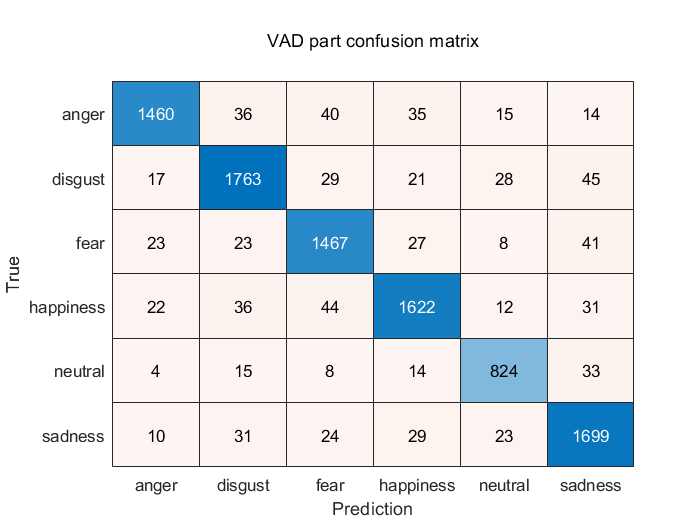

figure(1);
confusion_matrix1 = confusionchart(response_test,validationPredictions);
confusion_matrix1.Title = {'';'VAD part confusion matrix';''};
confusion_matrix1.YLabel = 'True';
confusion_matrix1.XLabel = 'Prediction';

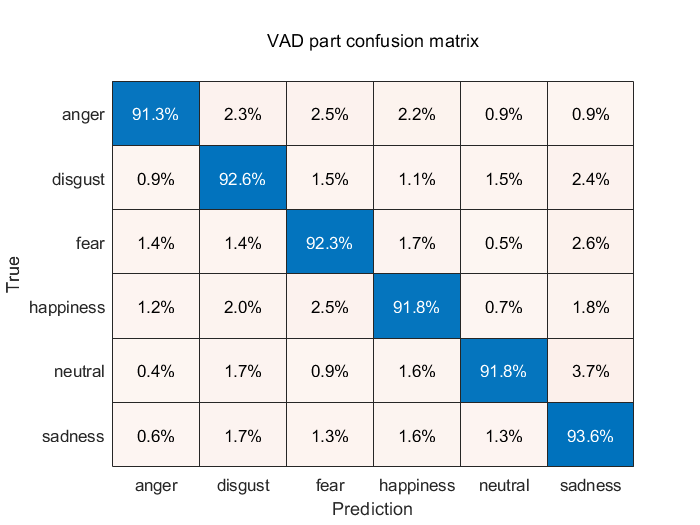


figure(2);
confusion_matrix2 = confusionchart(response_test,validationPredictions);
confusion_matrix2.Title = {'';'VAD part confusion matrix';''};
confusion_matrix2.YLabel = 'True';
confusion_matrix2.XLabel = 'Prediction';
% confusion_matrix2.RowSummary = 'row-normalized';
confusion_matrix2.Normalization = 'row-normalized';

- **Validation accuracy**

*The Validation accuracy is:*

validationAccuracy

validationAccuracy = 0.9229

- **Computational time**

t4 = clock;                         % tock
t_total=etime(t4,t1);

*Total time is:*

t_total

t_total = 170.5690